# Compute Fundamental Matrix

This example shows you how to compute the fundamental matrix. It uses the **least median of squares method** to find the inliers.

The points, matched_points1 and matched_points2, have been putatively matched.


matchedPoints_l = [995, 500; 1240, 387; 515, 484; 1448, 141; 1488, 382; 1435, 1740; 162, 994; 477, 979; 127, 464; 912, 652; 775, 707; 987, 939; 1371, 1490; 1394, 1175; 123, 132; 328, 87];
matchedPoints_r = [935, 512; 1170, 412; 452, 507; 1368, 174; 1408, 407; 1350, 1747; 52, 1012; 385, 1002; 59, 482; 845, 674; 705, 727; 917, 959; 1298, 1505; 1320, 1190; 59, 154; 269, 109];
[fLMedS, inliers] = estimateFundamentalMatrix(matchedPoints_l, matchedPoints_r, 'NumTrials', 4000);

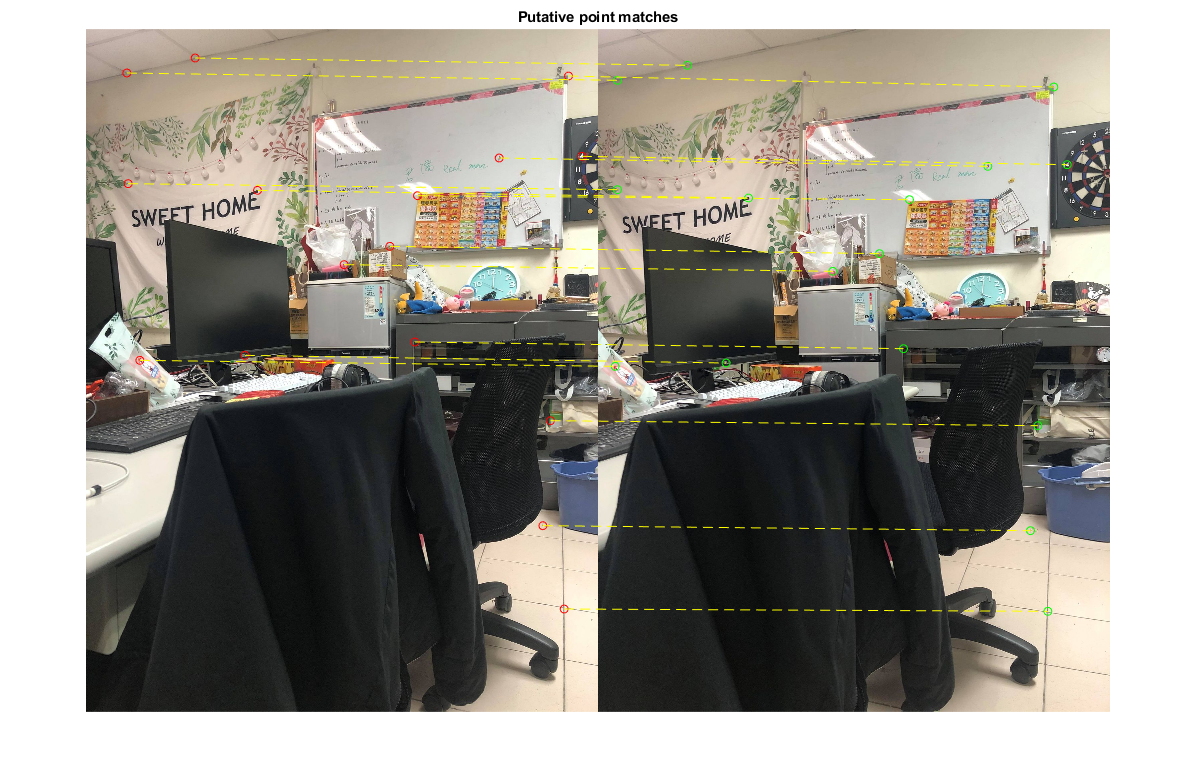

warning('off', 'Images:initSize:adjustingMag');
I1 = imread('left_view.jpg');
I2 = imread('right_view.jpg');
figure;
showMatchedFeatures(I1, I2, matchedPoints_l, matchedPoints_r, 'montage', 'PlotOptions',{'ro','go','y--'});
title('Putative point matches');

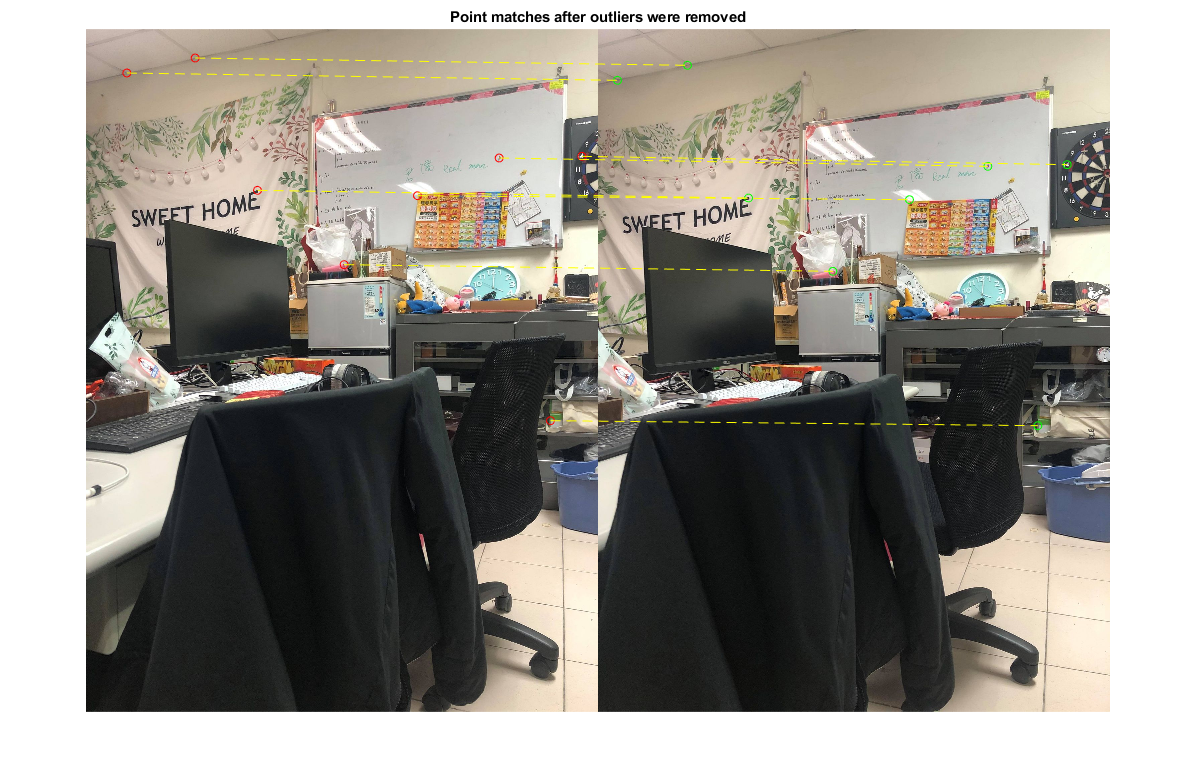

figure;
showMatchedFeatures(I1, I2, matchedPoints_l(inliers,:), matchedPoints_r(inliers,:),'montage','PlotOptions',{'ro','go','y--'});
title('Point matches after outliers were removed');

Show the inliers in the left image.

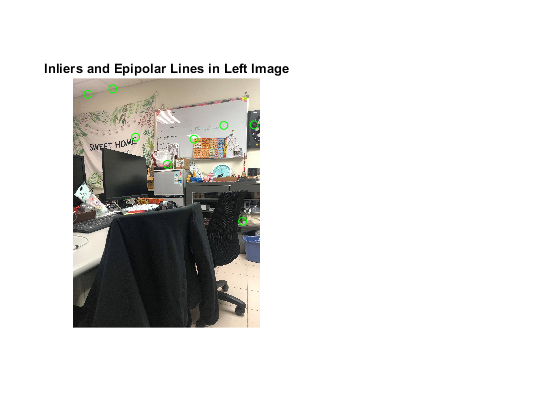

figure;
subplot(121);
imshow(I1);
title('Inliers and Epipolar Lines in Left Image'); hold on;
plot(matchedPoints_l(inliers,1), matchedPoints_l(inliers,2),'go')

Compute the epipolar lines in the left image.

epiLines = epipolarLine(fLMedS', matchedPoints_r(inliers,:));

Compute the intersection points of the lines and the image border.

points = lineToBorderPoints(epiLines, size(I1));

Show the epipolar lines in the left image

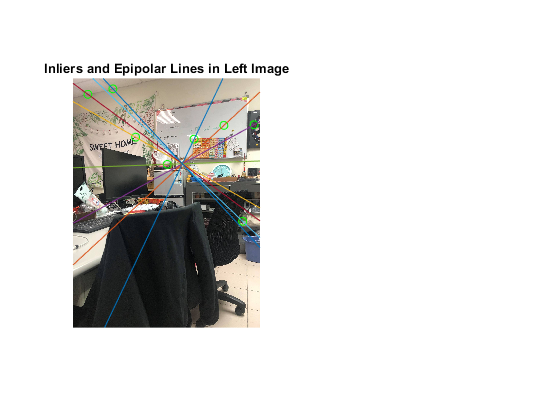

line(points(:,[1,3])',points(:,[2,4])');

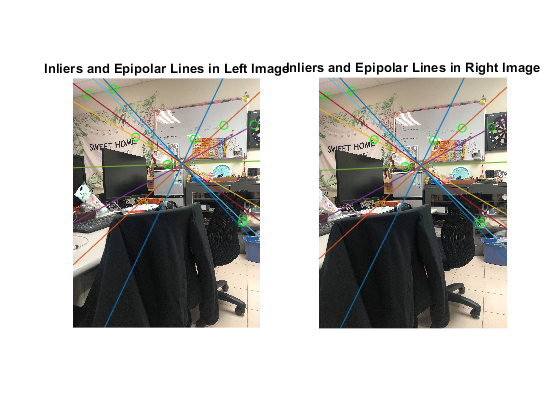

subplot(122); 
imshow(I2);
title('Inliers and Epipolar Lines in Right Image'); hold on;
plot(matchedPoints_r(inliers,1), matchedPoints_r(inliers,2),'go')
epiLines = epipolarLine(fLMedS,matchedPoints_l(inliers,:));
points = lineToBorderPoints(epiLines,size(I2));
line(points(:,[1,3])',points(:,[2,4])');